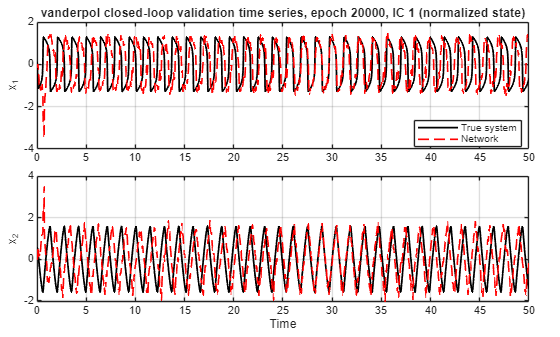

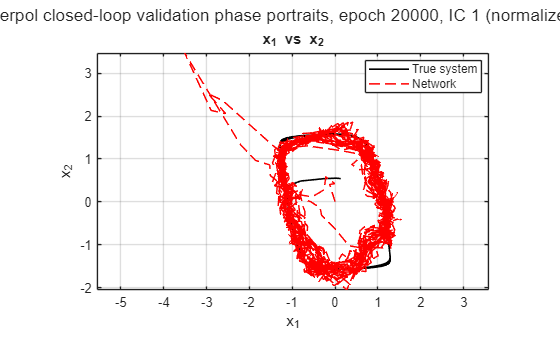

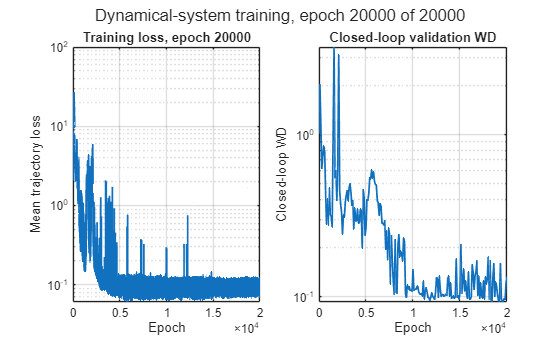

% Package orientation: Runnable training or experiment wrapper. It prepares task options, calls the shared API or experiment helper, and saves results for the matching test/analysis scripts. Hyperparameters are intentionally grouped under section headings below.

% GPU_implementation_dynamical_systems_vanderpol.mlx
% Train the vanderpol primary-decoder dynamical-system task and save the trained network.
% The saved result contains options, training loss history, and best bias vector.

clear; clc;
repo_root = project_root();
add_project_paths(repo_root);

%% ---------------- Task and Simulation ----------------
% system_name chooses the target dynamical system generator.
% seed fixes deterministic network generation and synthetic fallback trajectories.
% dyn_sys_rate is passed to the trajectory simulator when utilities are available.
% T_sim sets each sampled training snippet length; long_sim_time and burn_in_time define the long true simulation pool used for random contiguous snippets. closed_loop_validate_every controls periodic closed-loop rollout validation.
opts = struct();
opts.system_name = 'vanderpol';
opts.seed = 1;
opts.init_seed = opts.seed;
opts.split_seed = 42;
opts.dyn_sys_rate = 8;
opts.T_sim = single(5);
opts.long_sim_time = single(2000);
opts.burn_in_time = single(10);
opts.train_blocks = 1;
opts.closed_loop_validate_every = 100;
opts.closed_loop_validation_time = single(50);
opts.closed_loop_validation_ics = 5;
opts.closed_loop_test_time = single(50);
opts.closed_loop_test_ics = 5;
opts.closed_loop_ic_jitter = single(0.01);
opts.closed_loop_ic_seed = 1001;
opts.dt = single(1e-3);

%% ---------------- Network Size and Randomness ----------------
% N_hidden is the number of spiking neurons.
% N_rec is the recurrent decoder basis dimensionality used internally.
opts.N_hidden = 32000;
opts.N_rec = 10;

%% ---------------- Weight Scaling and Connectivity ----------------
% SCALE.enc controls input encoding, SCALE.rec recurrent feedback strength,
% and SCALE.dec the fixed primary decoder scale.
% NET fields control recurrent sparsity, variance correction, and Dale signs.
opts.SCALE = struct('enc', single(2), 'rec', single(0.05), 'dec', single(0.1));
opts.NET = struct('p_rec', 1, 'variance_correction', true, ...
    'dale', struct('enable', true, 'p_exc', 0.5, 'sign', []));

opts.arch = struct();
opts.arch.recurrent_mode = "low_rank";                  % "low_rank" or "full_rank"
opts.arch.decoder_mode = "signed";                      % "shared" or "signed"
opts.arch.signed_decoder_distribution = "uniform";     % "gaussian"/"normal" or "uniform"
opts.arch.full_rank_p_rec = single(1.0);
opts.arch.full_rank_remove_self_connections = true;
opts.arch.full_rank_storage = "auto";                   % "auto", "dense" or "sparse"
opts.arch.full_rank_sparse_threshold = single(0.10);
opts.arch.max_dense_full_rank_N = int32(6000);
opts.arch.max_sparse_full_rank_nnz = int64(20000000);
opts.arch.max_full_rank_recurrent_bytes = double(2.5 * 2^30);

%% ---------------- Free-Run Schedule ----------------
% use_multistep enables warmup/free-run cycles during training.
% W_warmup is the number of teacher-forced steps per cycle.
% H_free is the number of free-running feedback steps per cycle.
opts.use_multistep = true;
opts.W_warmup = round(0.030 / opts.dt);
opts.H_free = round(0.055/opts.dt);

%% ---------------- Neuron and Synapse Parameters ----------------
% tau_u/tau_w are membrane/adaptation time constants; tau_s_rise/tau_s_decay
% define the two-stage synaptic filter. Voltage terms are in mV.
% phi_u and delta_u define the surrogate-gradient shape around threshold.
opts.neuron = struct('tau_u', single(50e-3), 'tau_w', single(500e-3), ...
    'tau_s_rise', single(2e-3), 'tau_s_decay', single(50e-3), ...
    'E_L', single(-70), 'V_th', single(-50), 'V_reset', single(-65), ...
    'a_param', single(0), 'b_param', single(0.5), ...
    'phi_u', single(1), 'delta_u', single(0.8));

%% ---------------- Optimisation ----------------
% Only the bias vector B is trained. The output decoder W_out is fixed.
% epochs is the number of sampled training snippets/blocks processed.
% SCHED controls bias-learning-rate decay. adam controls bias optimizer moments.
opts.epochs = 2e5;
opts.SCHED = struct('type', 'exponential', 'lr_start', single(5e-2), 'lr_end', single(1e-3));
opts.adam = struct('b1', single(0.9), 'b2', single(0.999), 'eps', single(1e-8));
%% ---------------- Live Training Plots ----------------
% The training loop refreshes an inline Live Editor figure instead of saving plots to a folder.
% Set enable=false to disable plotting, or increase every to refresh less often.
opts.live_plot = struct('enable', true, 'every', 10);


% Optional local-only closed-loop validation trajectory plots. These reuse the
% validation rollout already computed for Wasserstein-distance validation; ARC
% wrappers omit this block to avoid GUI/file overhead on batch jobs.
opts.closed_loop_validation_plot = struct( ...
    'enable', true, ...
    'every', 1, ...
    'max_initial_conditions', 1, ...
    'max_points', 2000);


%% ---------------- Save Location ----------------
% TEST scripts load this exact file. Change model_file in both train and test
% scripts if you want to keep several saved networks for the same system.
model_dir = fullfile(repo_root, 'outputs', 'models');
if exist(model_dir, 'dir') ~= 7, mkdir(model_dir); end
model_file = fullfile(model_dir, sprintf('dynamical_systems_vanderpol_gpu_primary_seed%03d.mat', opts.seed));

%% ---------------- Run Training ----------------
% result.history is mean one-step/free-run training loss per epoch.

% result.best stores the lowest closed-loop-WD bias vector once validation runs; otherwise it falls back to lowest training loss.
result = snn_primary_api('train_dynamics', 'dynamical_systems', 'gpu', opts);
result.model_file = model_file;

Saved trained network to:
C:\Users\kaima\OneDrive - University of Calgary\Neural_networks_bias_learning\Spiking_neural_networks\SE adLIF\For Publication 3\GitHub_V2_multiple_architectures_working\outputs\models\dynamical_systems_vanderpol_gpu_primary_seed003.mat


save(model_file, 'result', '-v7.3');

     loss: 0.0953
       wd: 0.0930
        B: [32000×1 single]
    epoch: 18400



fprintf('Saved trained network to:\n%s\n', model_file);
disp(result.best);
